clc; clear all;
syms z q0 q1 q2 s0 s1;

# Discretización de la planta

%Modelo matemático del sistema para el segundo tanque:
K=0.23;
B=0.00171;
R=5.45;
L=3.8;
J=0.0019;
Ka=K;

numP=[K]

numP = 0.2300

denP=[L*J (R*J + L*B) (R*B+K*Ka) 0]

denP =     0.0072    0.0169    0.0622         0


Planta=tf(numP,denP)


Planta =
 
                  0.23
  -------------------------------------
  0.00722 s^3 + 0.01685 s^2 + 0.06222 s
 
Continuous-time transfer function.



%Definición del período de muestreo (50 veces más rápido que el tiempo de establecimiento de la planta)
tsla=0.5      %Tiempo de establecimiento lazo abierto

tsla = 0.5000

tm=(tsla)/50   %50 veces más rápido tiempo de muestreo, mas punticos

tm = 0.0100

%pero ojo son saturarlo 
%el profe mole dice 20 :) :) :)

%Discretización de la planta mediante retenedor de orden cero (Zero order hold)
PDisc=c2d(Planta,tm,'zoh')


PDisc =
 
  5.278e-06 z^2 + 2.099e-05 z + 5.217e-06
  ---------------------------------------
    z^3 - 2.976 z^2 + 2.953 z - 0.9769
 
Sample time: 0.01 seconds
Discrete-time transfer function.


zpk(PDisc)


ans =
 
  5.2783e-06 (z+3.71) (z+0.2664)
  ------------------------------
  (z-1) (z^2 - 1.976z + 0.9769)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



%Comparación plantas (Discreta vs Continua)
tini=0

tini = 0

tfin=6

tfin = 6

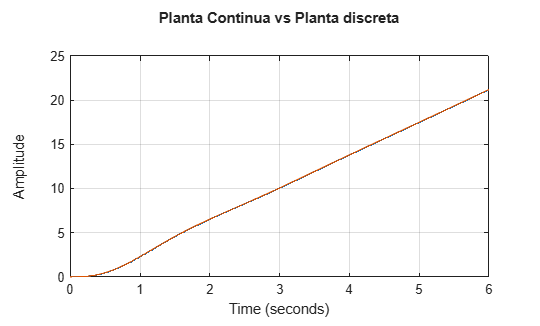

step(PDisc,tini:tm:tfin);
hold("on")
step(Planta,tini:tm:tfin);
title('Planta Continua vs Planta discreta')
grid on;


%Reescribimos la TF en potencias negativas

[numDisc,denDisc] = tfdata(PDisc, 'v')

numDisc = 1.0e-04 *

         0    0.0528    0.2099    0.0522


denDisc =     1.0000   -2.9761    2.9530   -0.9769


Kdisc1=numDisc(2)

Kdisc1 = 5.2783e-06

Kdisc2=numDisc(3)

Kdisc2 = 2.0990e-05

Kdisc3=numDisc(4)

Kdisc3 = 5.2170e-06

bdisc1=denDisc(2)

bdisc1 = -2.9761

bdisc2=denDisc(3)

bdisc2 = 2.9530

bdisc3=denDisc(4)

bdisc3 = -0.9769


%Se convierte a potencias positivas es un PDD^2 con un filtro de 
%segundo orden porque nuestra planta 
%es de orden 3 y el control de orden 2
%de PDD^2 tendria 5 entonces ponemos un filtro 
%tenemos otras dos incognitas s0 y s1 para tener 5 incognitas 
%para tner orden=ingocnitas
Controlador=((q0*z^2)+(q1*z)+q2)/(z^2-(s0*z)+s1)

$$Controlador = \frac{q_{0}\,z^{2}+q_{1}\,z+q_{2}}{z^{2}-s_{0}\,z+s_{1}}$$


numC=((q0*z^2)+(q1*z)+q2)

$$numC = q_{0}\,z^{2}+q_{1}\,z+q_{2}$$

denC=(z^2-(s0*z)+s1)

$$denC = z^{2}-s_{0}\,z+s_{1}$$


numP=Kdisc1*z^2 + Kdisc2*z + Kdisc3

$$numP = \frac{1557867476628247\,z^{2}}{295147905179352825856}+\frac{1548751951940845\,z}{73786976294838206464}+\frac{1539790995696075}{295147905179352825856}$$

denP=(z^3 + bdisc1*z^2 + bdisc2*z + bdisc3)

$$denP = z^{3}-\frac{6701528484498675\,z^{2}}{2251799813685248}+\frac{415598465111991\,z}{140737488355328}-\frac{2199846770978429}{2251799813685248}$$


PC=numC*numP + denC*denP

$$PC = \left(\frac{1557867476628247\,z^{2}}{295147905179352825856}+\frac{1548751951940845\,z}{73786976294838206464}+\frac{1539790995696075}{295147905179352825856}\right)\,\left(q_{0}\,z^{2}+q_{1}\,z+q_{2}\right)+\left(z^{2}-s_{0}\,z+s_{1}\right)\,\left(z^{3}-\frac{6701528484498675\,z^{2}}{2251799813685248}+\frac{415598465111991\,z}{140737488355328}-\frac{2199846770978429}{2251799813685248}\right)$$

PC=collect(PC) %organizado

$$PC = z^{5}+\left(\frac{1557867476628247\,q_{0}}{295147905179352825856}-s_{0}-\frac{6701528484498675}{2251799813685248}\right)\,z^{4}+\left(\frac{1548751951940845\,q_{0}}{73786976294838206464}+\frac{1557867476628247\,q_{1}}{295147905179352825856}+\frac{6701528484498675\,s_{0}}{2251799813685248}+s_{1}+\frac{415598465111991}{140737488355328}\right)\,z^{3}+\left(\frac{1539790995696075\,q_{0}}{295147905179352825856}+\frac{1548751951940845\,q_{1}}{73786976294838206464}+\frac{1557867476628247\,q_{2}}{295147905179352825856}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{6701528484498675\,s_{1}}{2251799813685248}-\frac{2199846770978429}{2251799813685248}\right)\,z^{2}+\left(\frac{1539790995696075\,q_{1}}{295147905179352825856}+\frac{1548751951940845\,q_{2}}{73786976294838206464}+\frac{2199846770978429\,s_{0}}{2251799813685248}+\frac{415598465111991\,s_{1}}{140737488355328}\right)\,z+\frac{1539790995696075\,q_{2}}{295147905179352825856}-\frac{2199846770978429\,s_{1}}{2251799813685248}$$

# Se diseña el polinomio deseado

zeta=0.7

zeta = 0.7000

ts=0.5%tiempo de estabilizacion del motor

ts = 0.5000

wn=4/(zeta*ts) %frecuencia natural 

wn = 11.4286

wd=wn*sqrt(1 - zeta^2) %frecuencia 

wd = 8.1616

PD=vpa(collect(((z^2 - z*(2*cos(wd*tm)*exp(-zeta*wn*tm)) + exp(-2*zeta*wn*tm))^2)*(z-0.05)),3)

$$PD = z^{5}-3.73\,z^{4}+5.27\,z^{3}-3.39\,z^{2}+0.883\,z-0.0363$$

# Se despejan las ganancias

PCcoeffs=coeffs(PC,'z','All')

$$PCcoeffs = \left(\begin{array}{cccccc} 1 & \frac{1557867476628247\,q_{0}}{295147905179352825856}-s_{0}-\frac{6701528484498675}{2251799813685248} & \frac{1548751951940845\,q_{0}}{73786976294838206464}+\frac{1557867476628247\,q_{1}}{295147905179352825856}+\frac{6701528484498675\,s_{0}}{2251799813685248}+s_{1}+\frac{415598465111991}{140737488355328} & \frac{1539790995696075\,q_{0}}{295147905179352825856}+\frac{1548751951940845\,q_{1}}{73786976294838206464}+\frac{1557867476628247\,q_{2}}{295147905179352825856}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{6701528484498675\,s_{1}}{2251799813685248}-\frac{2199846770978429}{2251799813685248} & \frac{1539790995696075\,q_{1}}{295147905179352825856}+\frac{1548751951940845\,q_{2}}{73786976294838206464}+\frac{2199846770978429\,s_{0}}{2251799813685248}+\frac{415598465111991\,s_{1}}{140737488355328} & \frac{1539790995696075\,q_{2}}{295147905179352825856}-\frac{2199846770978429\,s_{1}}{2251799813685248} \end{array}\right)$$

PDcoeffs=coeffs(PD,'z',"All")

$$PDcoeffs = \left(\begin{array}{cccccc} 1 & -3.7301740403636358678340911865234 & 5.2742165217641741037368774414062 & -3.3905478417873382568359375 & 0.88295090961037203669548034667969 & -0.036307451853645034134387969970703 \end{array}\right)$$

eq=PCcoeffs==PDcoeffs

$$eq = \left(\begin{array}{cccccc} 1=1 & \frac{1557867476628247\,q_{0}}{295147905179352825856}-s_{0}-\frac{6701528484498675}{2251799813685248}=-3.7301740403636358678340911865234 & \frac{1548751951940845\,q_{0}}{73786976294838206464}+\frac{1557867476628247\,q_{1}}{295147905179352825856}+\frac{6701528484498675\,s_{0}}{2251799813685248}+s_{1}+\frac{415598465111991}{140737488355328}=5.2742165217641741037368774414062 & \frac{1539790995696075\,q_{0}}{295147905179352825856}+\frac{1548751951940845\,q_{1}}{73786976294838206464}+\frac{1557867476628247\,q_{2}}{295147905179352825856}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{6701528484498675\,s_{1}}{2251799813685248}-\frac{2199846770978429}{2251799813685248}=-3.3905478417873382568359375 & \frac{1539790995696075\,q_{1}}{295147905179352825856}+\frac{1548751951940845\,q_{2}}{73786976294838206464}+\frac{2199846770978429\,s_{0}}{2251799813685248}+\frac{415598465111991\,s_{1}}{140737488355328}=0.88295090961037203669548034667969 & \frac{1539790995696075\,q_{2}}{295147905179352825856}-\frac{2199846770978429\,s_{1}}{2251799813685248}=-0.036307451853645034134387969970703 \end{array}\right)$$

[q0,q1,q2,s0, s1]=solve(eq,[q0,q1,q2,s0, s1])

$$q0 = 1263.5348313182156612100803816185$$

$$q1 = -2418.1415584675161582157565960515$$

$$q2 = 1158.9928901961824634512055978231$$

$$s0 = 0.76076681665882540489281264407121$$

$$s1 = 0.04335419360252873416363217298234$$

q0=double(q0)

q0 = 1.2635e+03

q1=double(q1)

q1 = -2.4181e+03

q2=double(q2)

q2 = 1.1590e+03

s0=double(s0)

s0 = 0.7608

s1=double(s1)

s1 = 0.0434